# ** GRN Project 2**

Five gene regulatory network motifs are simulated in the code `GRNs_for_HW2.m`. These are:

- Direct negative feedback

- Indirect negative feedback

- Double negative feedback

- Incoherent feed-forward

- Repressilator

For most gene regulatory motifs, as an activating input is increased, the steady-state amount of protein increases gradually. The *biological function* of "ultrasensitivity" or "switch-like response" is a phenomena where the steady-state amount of protein increases slowly, then suddenly, then slowly again. 

# HW2 

Find at least one of the 5 network motifs listed above that produces a switch-like response. Plot the amount of protein as a function of input concentration, showing the switch-like graph.

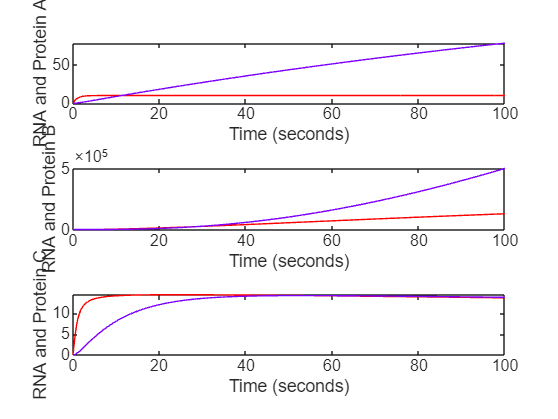

% Degradation rates
% Degradation rates
delta_ma = 0.01;   % Reduced RNA degradation rate for A
gamma_pa = 2.0;    % Increased production rate for A
delta_pa = 0.0001;   % Further reduced degradation rate for A

delta_mb = 0.01;   % Reduced RNA degradation rate for B
gamma_pb = 2.0;    % Increased production rate for B
delta_pb = 0.01;   % Further reduced degradation rate for B

delta_mc = 0.01;   % Reduced RNA degradation rate for C
gamma_pc = 2.0;    % Increased production rate for C
delta_pc = 0.0001;   % Further reduced degradation rate for C

% Production rates
gamma_ma = 50;     % Very high production rate for A

Kab = 100;         % Strong activation of B by A
gamma_mb = @(pa) 20 .* (1 + (Kab * pa).^2); % Increase the Hill coefficient

Kac = 100;         % Strong activation of C by A
Kbc = 100;         % Strong inhibition of B by A
gamma_mc = @(pa, pb) 20 .* (1 + (Kac * pa).^2) ./ (1 + (Kbc * pb).^2); % Increase the Hill coefficient

% Define the ODE system with updated parameters
dxdt = @(t,x)[dmadt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dpadt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dmbdt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dpbdt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dmcdt(x(1),x(2),x(3),x(4),x(5),x(6),t);
              dpcdt(x(1),x(2),x(3),x(4),x(5),x(6),t)];

% Initial condition
initialCondition = [0,0,0,0,0,0];

% Simulation
[T, X] = ode45(dxdt, [0.0,100], initialCondition);

% Plot the results
figure(); clf; 
subplot(3,1,1);hold on; box on;
plot(T,X(:,1),'-r'); % RNA for A
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % Protein A
ylabel('RNA and Protein A')
xlabel('Time (seconds)')

subplot(3,1,2);hold on; box on;
plot(T,X(:,3),'-r'); % RNA for B
plot(T,X(:,4),'-', 'color', [0.5 0 1]); % Protein B
ylabel('RNA and Protein B')
xlabel('Time (seconds)')

subplot(3,1,3);hold on; box on;
plot(T,X(:,5),'-r'); % RNA for C
plot(T,X(:,6),'-', 'color', [0.5 0 1]); % Protein C
ylabel('RNA and Protein C')
xlabel('Time (seconds)')